# **Procesamiento de Imagenes Digitales**

# **Taller 2**

- Lea la imagen `skeleton`, y visualícela junto a su negativo en subplot horizontal en la figura 1.

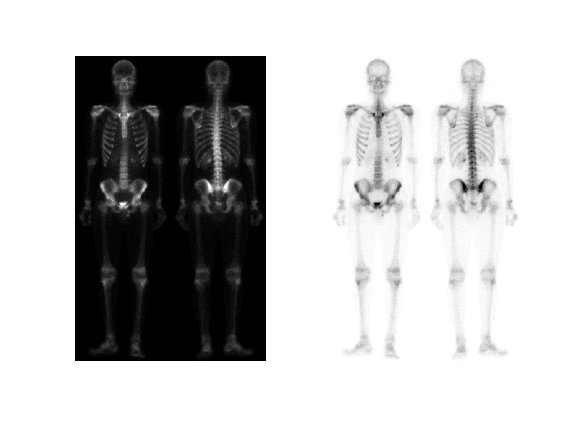

I=imread('skeleton.tif');
N=imadjust(I, [0 1],[1 0]);
figure(1);
subplot(1,2,1);imshow(I)
subplot(1,2,2);imshow(N)

- Lea la imagen aerial, mejore su contraste usando las transformaciones: logarítmica y de ecualización. Visualícelas (la imagen original y las 2 transformadas) junto con su correspondiente histograma en un subplot horizontal, en las figuras 2, 3 y 4. 

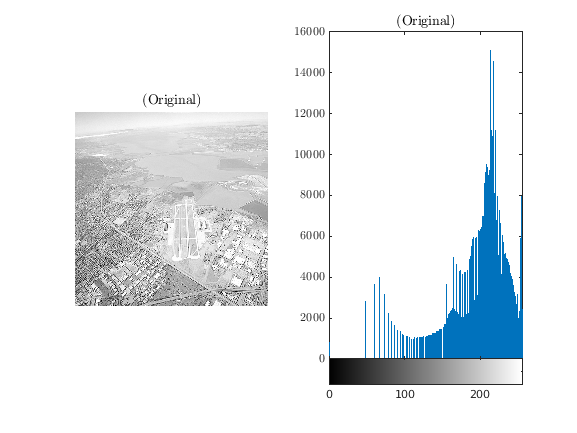

I=imread('aerial.tif');
L=im2uint8(mat2gray(log(1+double(I))));
Eq=histeq(I);
figure(2);
subplot(1,2,1);imshow(I);title('(Original)','Interpreter','latex');

subplot(1,2,2);imhist(I);title('(Original)','Interpreter','latex');ylim('auto');set(gca,'ticklabelinterpreter','latex');

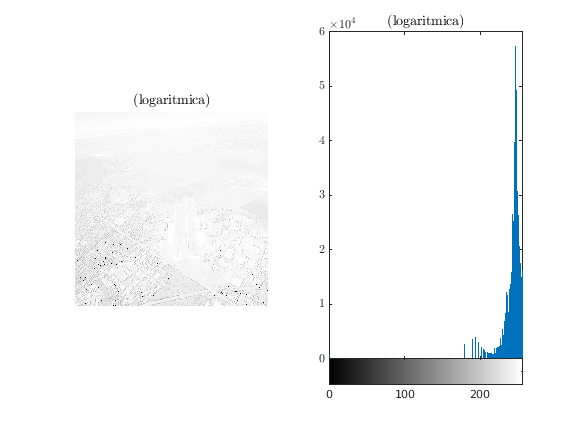

figure(3);
subplot(1,2,1);imshow(L);title('(logaritmica)','Interpreter','latex');

subplot(1,2,2);imhist(L);title('(logaritmica)','Interpreter','latex');ylim('auto');set(gca,'ticklabelinterpreter','latex');

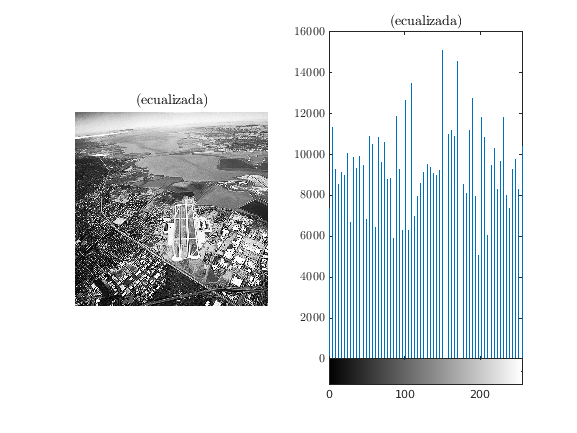

figure(4);
subplot(1,2,1);imshow(Eq);title('(ecualizada)','Interpreter','latex');

subplot(1,2,2);imhist(Eq);title('(ecualizada)','Interpreter','latex');ylim('auto');set(gca,'ticklabelinterpreter','latex');

Según su análisis de los histogramas, ¿Cuál transformación es más apropiada para mejorar el contraste de la imagen `aerial` y por qué?

Como vemos la tranfomada por ecualización resulta mas convenientes para imagenes que presentan un contrase suave, por el contrario podemos usar la transformada logaritmica a imagenes que presentan un contraste mas fuerte pero no lo suficiente para poder distingir las distintas intensidades de manera mas clara, por lo que la transformada por ecualización es mas apropiada para aerial.tif, encambio una transformada logaritmica nos resultaria mejor para la imagen de skeleton.tif

- Lea la imagen kidney, mejore su contraste usando la transformación de especificación de histograma para los niveles 8, 128 y 256. Visualícelas junto con su correspondiente histograma en un subplot horizontal, en las figuras 5, 6, 7 y 8. 

I=imread('kidney.tif');
Eq1=histeq(I,8);
Eq2=histeq(I,128);
Eq3=histeq(I,256);
%original
figure(5);
subplot(1,2,1);imshow(I)
subplot(1,2,2);imhist(I);ylim('auto')
figure(6);% nivel de intensidad de 8
subplot(1,2,1);imshow(Eq1)
subplot(1,2,2);imhist(Eq1);ylim('auto')
figure(7);% nivel de intensidad de 128
subplot(1,2,1);imshow(Eq2)
subplot(1,2,2);imhist(Eq2);ylim('auto')
figure(8);% nivel de intensidad de 256
subplot(1,2,1);imshow(Eq3)
subplot(1,2,2);imhist(Eq3);ylim('auto')

Al concentrar su atención sobre las imágenes transformadas, ¿La imagen de cuantos niveles de intensidad le resulta más útil para visualizar el riño en observación?, justifique.

 A pesar de la calidad de la imagen en los niveles de intensidad mas altos, nos resulta mas útil la información que nos aporta un nivel de intensidad de bajo, ya que nos da una idea general mas clara de las areas posiblemente afectadas, en cambio en los niveles de intensidad superiores nos encontramos que la imagen a pesar de tener una mejor calidad, no son tan marcadas las zonas, que en este caso es lo que nos intereza.